In this notebook, we train a fault diagnosis model based on the simulation data from the digital twin, and test the trained model on a real robot. 

# Download the dataset

First, we download previously generated training (through simulation) and test (from a real robot) dataset. The dataset should be first downloaded and unzipped into a local subdirectory called `dataset`. In `dataset/`, you will find three subfolders:

- trainingDatasets: Contain the training data;

- testDatasetsOriginal: Contain the test data in the original format collected from the robot

- testDatasets: Contain the test data transformed into the Matlab format.

- dataset_descrpitions.txt: Describe the settings for generating each training and test dataset.

You can either download the dataset from [this link](http://%27https//nextcloud.centralesupelec.fr/s/7AR6aamBZNXcRM8/download'). Then, you should unzip the downloaded file and put the folder `dataset under the root dictionary. Or you can directly run this code to download the dataset. Depending on the network condition, it migth take up to 20 mins to download the dataset.`

url = 'https://nextcloud.centralesupelec.fr/s/7AR6aamBZNXcRM8/download';
downloadFolder = fullfile('../', 'dataset');
rootDict = fullfile('../');
if ~exist(downloadFolder, 'dir')
    options = weboptions('Timeout', 30);
    loc = websave([downloadFolder '.zip'], url, options);
    unzip(loc, rootDict);
end

# Data preparation

## Load the training data

We load the original dataset in `trainingDataFolderName`, and create two cell arrays:

- dataTables: A cellarray of 3600 elements, each element is a dataTable, contains all the available features.

- y: A cellarray of 3600 elements, each element is the label (str).

Here, the training dataset used is `20141016. `

clear; clc; close all;
warning('off');

% Set random seed for reproduction purpose.
rng(42);

trainingDataFolderName = '20241016';
testDataFolderName = '20241016';
doTraining = true;

mdlName = ['mdlTrajCmdTrajResidual' 'TrData' trainingDataFolderName 'TestData' testDataFolderName '.mat'];
% Define the path to check for 'conc_dataset.mat'
pathLoggedTrainingData = ['../dataset/trainingDatasets/' trainingDataFolderName '/training_dataset.mat'];
pathTrainingData = ['../dataset/trainingDatasets/' trainingDataFolderName '/'];

% Define a DataLoader instance.
% Define the length of simulation and the corresponding sequence length.
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);
dataLoader.shuffle = false; % Shuffle the data.
dataLoader.pathTrainingDataset = pathTrainingData;
dataLoader.pathLoggedTrainingData = pathLoggedTrainingData;
[X, y] = dataLoader.loadTrainingData();

Loaded data from ../dataset/trainingDatasets/20241016/training_dataset.mat


We can print an example of all the features.

X{1}

ans = 1000×13 table
    Timestamps    Motor1Cmd    Motor2Cmd     Motor3Cmd      Motor4Cmd     Motor5Cmd    DesiredTrajectory-x    DesiredTrajectory-y    DesiredTrajectory-z    RealizedTrajectory-x    RealizedTrajectory-y    RealizedTrajectory-z                             matFilePath                          
    __________    _________    _________    ___________    ___________    _________    ___________________    ___________________    ___________________    ____________________    ____________________    ____________________    ____________________________

## Split into training and validation dataset.

Here, we split the training dataset into training and validation dataset using a training ratio of 90%.

% Shuffle the dataset using the cvpartition function
training_ratio = .9;
n_dataset = numel(X);
training_size = floor(training_ratio*n_dataset);
cvObj = cvpartition(y, 'HoldOut', training_size);
idx = cvObj.test;

% Split into training and test data based on training size specified
X_train = X(idx');
X_val = X(~idx');
y_train = categorical(y(idx'));
y_val = categorical(y(~idx'));

## Load the testing dataset.

Then, we load the testing data from the real robot.

dataLoader.pathLoggedTestData = ['../dataset/testDatasets/' testDataFolderName '/real_testing_dataset.mat'];
dataLoader.pathTestDataset = ['../dataset/testDatasets/' testDataFolderName '/'];
dataLoader.pathOriginalTestData = ['../dataset/testDatasetsOriginal/' testDataFolderName '/'];
dataLoader.nTrajPerLabelTestDataset = 10;
dataLoader.labelList = {'Healthy', ...
    'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
    'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'};
    
[X_test, y_test] = dataLoader.loadTestingData();

Loaded data from ../dataset/testDatasets/20241016/real_testing_dataset.mat


y_test = categorical(y_test);

X_test{1}

ans = 1000×13 table
    Timestamps    Motor1Cmd     Motor2Cmd    Motor3Cmd    Motor4Cmd    Motor5Cmd    DesiredTrajectory-x    DesiredTrajectory-y    DesiredTrajectory-z    RealizedTrajectory-x    RealizedTrajectory-y    RealizedTrajectory-z                           matFilePath                        
    __________    __________    _________    _________    _________    _________    ___________________    ___________________    ___________________    ____________________    ____________________    ____________________    ______________________________________

## Training and validation set creation

We randomly split a dataset and train a LSTM.

We can show the distribution of classes in the training and testing dataset, to make sure the seperation is fair.

summary(y_train);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     360          360                             360                360                             360                360                             360                360                             360           


summary(y_val);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     40           40                              40                 40                              40                 40                              40                 40                              40            


summary(y_test);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     10           10                              10                 10                              10                 10                              10                 10                              10            


# Pre-processing and feature engineering

In this section, we preprocess the data and augument the dataset by adding some new features from feature engineering.

X_train = dataLoader.extractFeaturesTrajCmdTrajResidual(X_train);
X_val = dataLoader.extractFeaturesTrajCmdTrajResidual(X_val);
X_test = dataLoader.extractFeaturesTrajCmdTrajResidual(X_test);

window = 10;
X_train = pre_process(X_train, window);
X_val = pre_process(X_val, window);
X_test = pre_process(X_test, window);

## Normalize Training Features

Networks will often train better when normalized. Calculate the mean and standard deviation and normalize each element of the training feature set. 

[X_train, M, S] = normalize_features(X_train);
[X_val, ~, ~] = normalize_features(X_val, M, S);
[X_test, ~, ~] = normalize_features(X_test, M, S);

# Training and evaluating the model

Use an LSTM network. An LSTM layer learns long-term dependencies between time steps of time series or sequence data. The first lstmlayer will have 100 hidden units and output the sequence data. Then a dropout layer will be used to reduce probability of overfitting. The second lstmlayer will output just the last step of the time sequence.

layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

## Define Network Hyperparameters

miniBatchSize = 32;
validationFrequency = floor(numel(X_train)/miniBatchSize);
options = trainingOptions("adam", ...
    "MaxEpochs",30, ...
    "MiniBatchSize",miniBatchSize, ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "Shuffle","every-epoch", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",20,...
    'ValidationData',{X_val, y_val}, ...
    'ValidationFrequency',validationFrequency);

## Train The Network

This network takes about 100 seconds to train on an NVIDIA RTX 2080 GPU.

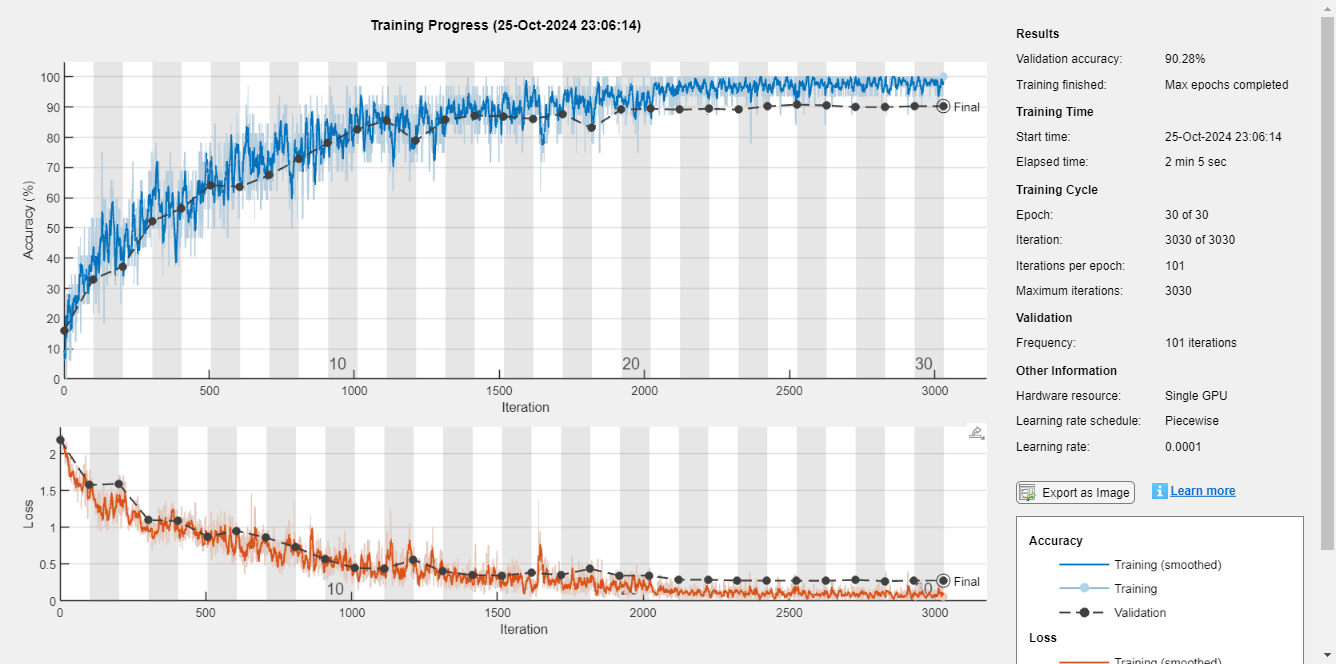

if doTraining || ~isfile(mdlName)
    diagnosisNet = trainNetwork(X_train, y_train, layers, options);
    save(mdlName, 'diagnosisNet');
else
    load(mdlName, 'diagnosisNet');
end

## Test The Network

Now that the network has been trained, we can test it on the validation data. 

y_pred = classify(diagnosisNet, X_test);

View the confusion chart for the test results:

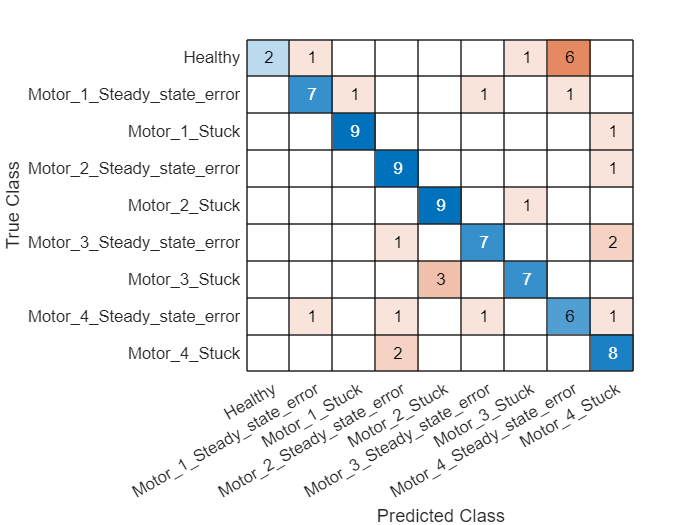

figure()
cm = confusionchart(y_test', y_pred);

View the overall accuracy percentage of the validation and test results:

[accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_test, y_pred);
% Display the results
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 71.11%


class_names = categories(y_test);
for i = 1:numel(class_names)
    fprintf('Class %d (%s): Precision = %.2f, Recall = %.2f, F1 Score = %.2f\n', i, class_names{i}, precision(i), recall(i), f1Score(i));
end

Class 1 (Healthy): Precision = 1.00, Recall = 0.20, F1 Score = 0.33
Class 2 (Motor_1_Steady_state_error): Precision = 0.78, Recall = 0.70, F1 Score = 0.74
Class 3 (Motor_1_Stuck): Precision = 0.90, Recall = 0.90, F1 Score = 0.90
Class 4 (Motor_2_Steady_state_error): Precision = 0.69, Recall = 0.90, F1 Score = 0.78
Class 5 (Motor_2_Stuck): Precision = 0.75, Recall = 0.90, F1 Score = 0.82
Class 6 (Motor_3_Steady_state_error): Precision = 0.78, Recall = 0.70, F1 Score = 0.74
Class 7 (Motor_3_Stuck): Precision = 0.78, Recall = 0.70, F1 Score = 0.74
Class 8 (Motor_4_Steady_state_error): Precision = 0.46, Recall = 0.60, F1 Score = 0.52
Class 9 (Motor_4_Stuck): Precision = 0.62, Recall = 0.80, F1 Score = 0.70


# Discussions

When applied to real data, we can see a signifiant drop of model performance. The most severely impacted class is the normal class: Most of the normal samples are misclassifed to the otehr failure classes. This is mainly because in the real robot, there are errors caused by noise. So even for normal data without failure, the residual values tend to be larger than the simulation data.

More generally, the feature distribution is different between the training data and the test data. The following code visualize the distributional difference. A difference is clear from the results.

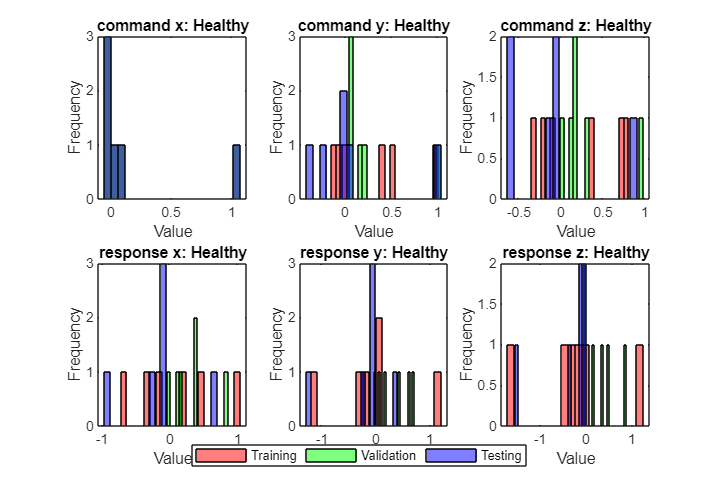

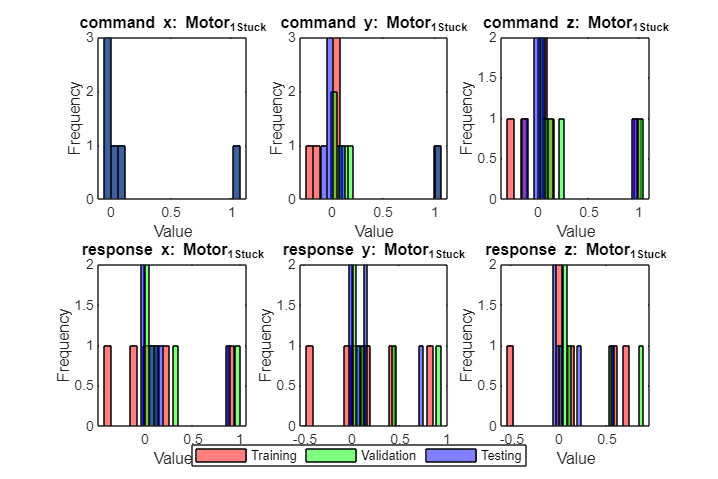

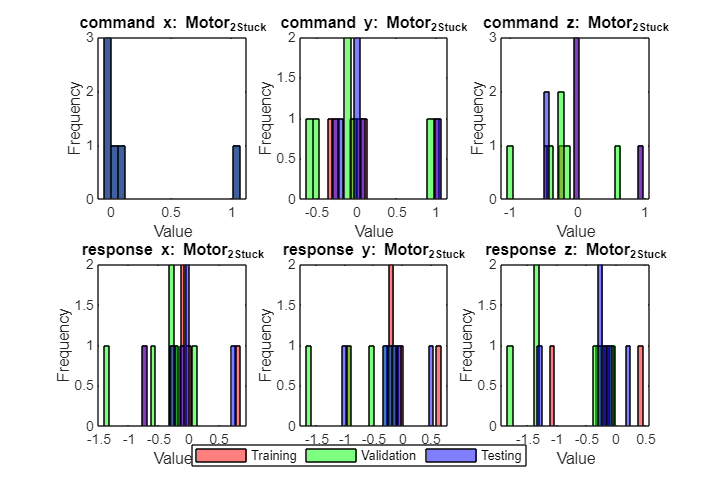

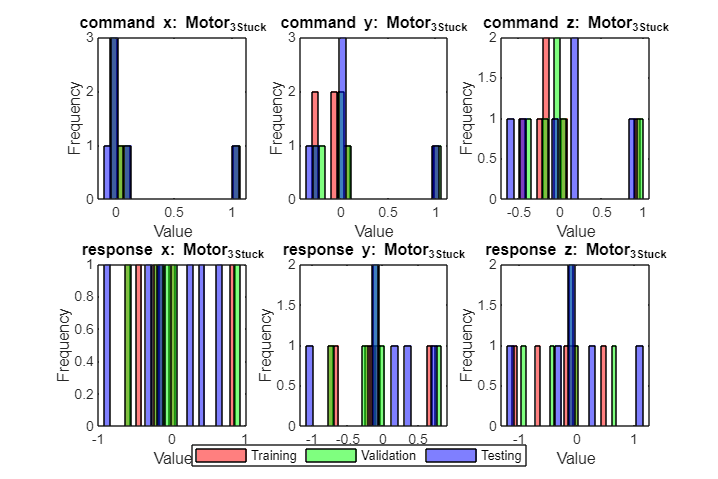

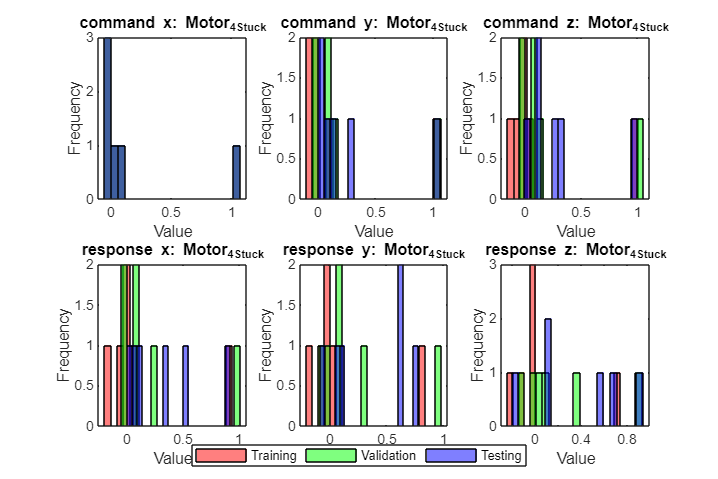

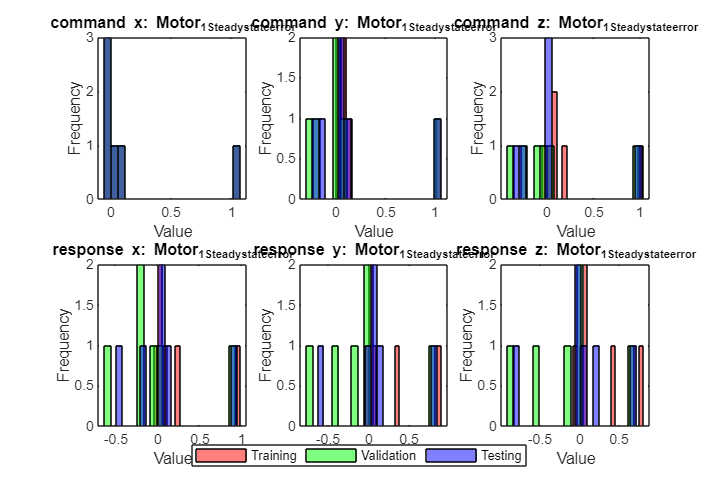

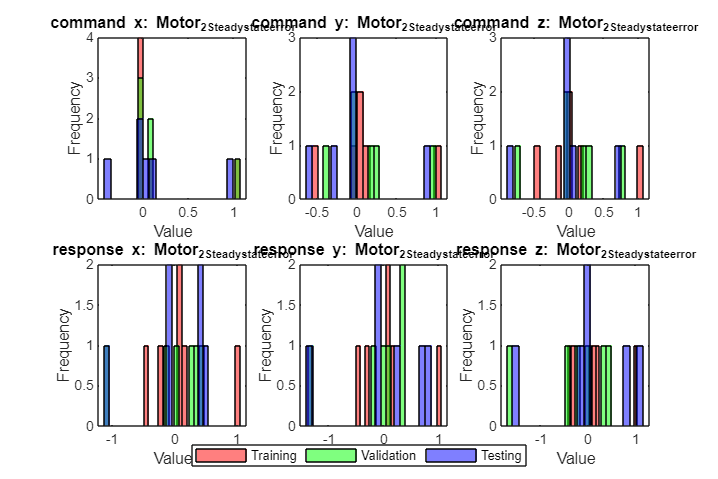

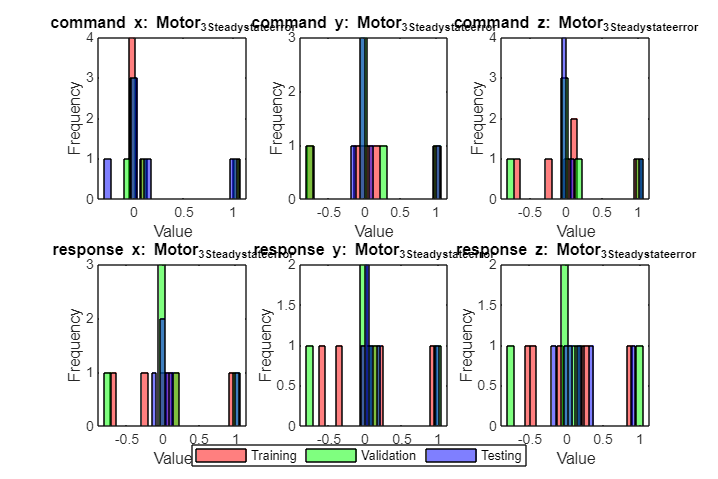

for idx = 1:9
    label = dataLoader.labelList{idx};

    plt_feature_dist(X_train, X_val, X_test, y_train, y_val, y_test, label);
end

# Supporting functions

function [X, M, S] = normalize_features(X, M, S)
    % This function normalizes the features.
    % Input: X is an cell array of 1*n_data, whose elements are matrixs of
    % (n_seq, n_features).

    if nargin == 1
        % Concatenate all the features. Creat a matrix of (n_seq*n_data,
        % n_features).
        allFeatures = cat(1, X{:});
    
        % Do the normalization.
        M = mean(allFeatures);
        S = std(allFeatures);
    end
    
    for index = 1:numel(X)
       X{index} =  ((X{index} - M)./S)';
    end
end


function X = pre_process(X, window)
    for i = 1:numel(X)
        X_tmp = X{i};
        X{i} = X_tmp(1:window:end, :);
    end
end


function plt_feature_dist(X_train, X_val, X_test, y_train, y_val, y_test, label)

f1 = figure();
f1.Position = [10 10 900 600];
X_exp_tr = X_train(y_train==label);
X_exp_val = X_val(y_val==label);
X_exp_test = X_test(y_test==label);

X_exp_tr = X_exp_tr{:};
X_exp_val = X_exp_val{:};
X_exp_test = X_exp_test{:};

titles = {'command x', 'command y', 'command z',...
    'response x', 'response y', 'response z'};

numBins = 20;
for i = 1:6
    subplot(2, 3, i);

    x1 = X_exp_tr(:, i);
    x2 = X_exp_val(:, i);
    x3 = X_exp_test(:, i);

    % Plot the histograms
    histogram(x1, numBins, 'FaceColor', 'r', 'FaceAlpha', 0.5);  % Red histogram
    hold on;  % Keep the current plot
    histogram(x2, numBins, 'FaceColor', 'g', 'FaceAlpha', 0.5);  % Green histogram
    histogram(x3, numBins, 'FaceColor', 'b', 'FaceAlpha', 0.5);  % Blue histogram
    hold off;  % Release the plot hold

    % Add labels
    xlabel('Value');
    ylabel('Frequency');
    title([titles{i} ': ' label]);
end
legend('Training', 'Validation', 'Testing', 'Position', [0.5 0.05 0 0], 'Orientation', 'horizontal');

end